% priprava podatkov
data = load('VAJA3.mat');

% Priprava podatkov
A_FLOW = data.A_FLOW;
T_H2O = data.T_H2O;
C_ACID = data.C_ACID;
I_EFF = data.I_EFF;
X = [A_FLOW, T_H2O, C_ACID];
Y = I_EFF;

% Izbira standardizacijskih metod
standardization_methods = ["min-max", "z-score", "none"];


    "LSE Standardization Method: "    "min-max"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


    "LSE Standardization Method: "    "z-score"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


    "LSE Standardization Method: "    "none"



Regression Coefficients: 0.715640 1.295286 -0.152123 -39.919674


parameter variance: 0.018187 0.135442 0.024428 141.514741


Normalized Root Mean Squared Error (NRMSE):  0.287


Error Variance: 8.941, Error Bias: 0.000, Error Standard deviation: 2.990


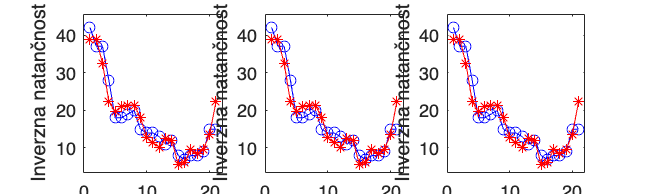



% Zanka za LSE
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    % Standardizacija podatkov
    [X_n, Y_n] = abc(X, Y, n);
    
    % Dodajanje stolpca enic za presledek
    X_n = [X_n, ones(size(X_n, 1), 1)];
    X_c = [X, ones(size(X, 1), 1)];

    % Izračun parametrov beta z metodo LSE
    beta_hat_std = (X_n' * X_n) \ (X_n' * Y_n);

    % Transformacija parametrov nazaj v originalni prostor, če je potrebno
    if n == "min-max"
        min_X = min(X);
        max_X = max(X);
        min_Y = min(Y);
        max_Y = max(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* (max_Y - min_Y) ./ (max_X - min_X);
        beta_hat_0 = beta_hat_std(end) * (max_Y - min_Y) + min_Y - sum(beta_hat_X .* min_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';

    elseif n == "z-score"
        mu_X = mean(X);
        sigma_X = std(X);
        mu_Y = mean(Y);
        sigma_Y = std(Y);

        beta_hat_X = beta_hat_std(1:end-1)' .* sigma_Y ./ sigma_X;
        beta_hat_0 = beta_hat_std(end) * sigma_Y + mu_Y - sum(beta_hat_X .* mu_X);
        beta_hat = [beta_hat_X, beta_hat_0];

        % Izračun predvidenih vrednosti I_EFF
        I_EFF_pred = X_c * beta_hat';
    elseif n == "none"
        beta_hat = beta_hat_std';
        I_EFF_pred = X_c * beta_hat';
    end

    % Izračun napake, kovariančne matrike in NRMSE
    error_LSE = I_EFF - I_EFF_pred;
    cov_matrix_LSE = pinv(X_c' * X_c) * (error_LSE' * error_LSE) / (size(X_c, 1) - size(X_c, 2));
    NRMSE_LSE = sqrt(sum((error_LSE).^2) / (size(X, 1))) / std(Y);
    STD_LSE = std(error_LSE);

    % Prikaz rezultatov
    disp(['LSE Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', beta_hat);
    fprintf('parameter variance: %f %f %f %f\n', diag(cov_matrix_LSE));
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_LSE);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation: %.3f\n', var(error_LSE), mean(error_LSE), STD_LSE);

    % Prikaz pričakovanih in izračunanih vrednosti
    subplot(1, 3, i);
    plot(1:length(I_EFF), I_EFF, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(I_EFF), I_EFF_pred, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Meritev');
    ylabel('Inverzna natančnost');
    %title(sprintf('Standardization: %s', n));
    ylim([min(I_EFF) - 0.1 * range(I_EFF), max(I_EFF) + 0.1 * range(I_EFF)]);
    xlim([0, length(I_EFF) + 1]);
    hold off;
end

% Load data
data = load('VAJA3.mat');

% Data Preparation
X = [data.A_FLOW, data.T_H2O, data.C_ACID];
Y = data.I_EFF;

% Choose the standardization methods
standardization_methods = ["min-max"];

% Initialize figure for plotting
figure;

% Loop through each standardization method
for i = 1:length(standardization_methods)
    n = standardization_methods(i);
    
    %% PCA Regression
    % Standardize the data
    [X_n, Y_n] = abc(X, Y, n);

    % Combine and center the data
    Z = [X_n, Y_n];
    nn = size(Z, 1);
    Z_centered = Z - mean(Z);

    % Calculate the covariance matrix
    F = (Z_centered' * Z_centered) / (nn - 1);

    % Perform Singular Value Decomposition (SVD)
    [P, ~] = svd(F);

    % Get the coefficients of the first principal component
    coeff = P(:, end);

    % Calculate the explicit model coefficients
    if n == "min-max" 
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* (max(Y) - min(Y)) ./ (max(X) - min(X));
        d = sum(a .* (mean(X_n) .* (max(Y) - min(Y)))) + mean(Y_n) * (max(Y) - min(Y)) + min(Y) + (max(Y) - min(Y)) .* a ./ (max(X) - min(X)) * min(X)';
    elseif n == "z-score"
        a = coeff(1:end-1)' ./ coeff(end);
        c = -a .* std(Y) ./ std(X);
        d = sum(a .* (mean(X_n) .* std(Y))) + mean(Y_n) * std(Y) + mean(Y) + std(Y) .* a ./ std(X) * mean(X)';
    else
        c = -coeff(1:end-1)' ./ coeff(end);
        d = mean(Y_n) - sum(c .* mean(X_n));
    end

    % Construct the PCA model coefficients
    model_PCA_poly = [c d];

    % Calculate predicted I_EFF
    model_PCA = sum(model_PCA_poly .* horzcat(X, ones(size(X, 1), 1)), 2);

    % Calculate the error and NRMSE
    error_PCA = Y - model_PCA;
    NRMSE_PCA = sqrt(sum((error_PCA).^2) / size(X, 1)) / std(Y);
    STD_PCA = std(error_PCA);

    % Display results
    disp(['PCA Standardization Method: ', n]);
    fprintf('Regression Coefficients: %f %f %f %f\n', model_PCA_poly);
    fprintf('Normalized Root Mean Squared Error (NRMSE):  %.3f\n', NRMSE_PCA);
    fprintf('Error Variance: %.3f, Error Bias: %.3f, Error Standard deviation %.3f\n', var(error_PCA), mean(error_PCA), STD_PCA);

    % Plot the expected Y and calculated Y
    subplot(1, 3, i);
    plot(1:length(Y), Y, 'bo-', 'DisplayName', 'Expected Y (I_{EFF})');
    hold on;
    plot(1:length(Y), model_PCA, 'r*-', 'DisplayName', 'Calculated Y (I_{EFF_{pred}})');
    xlabel('Meritev');
    ylabel('Inverzna natančnost');
    title(sprintf('Standardization: %s', n));
    ylim([min(Y) - 0.1 * range(Y), max(Y) + 0.1 * range(Y)]);
    xlim([0, length(Y) + 1]);
    hold off; 
end

    "PCA Standardization Method: "    "min-max"



Regression Coefficients: 0.798908 1.207175 -0.218784 -37.340803


Normalized Root Mean Squared Error (NRMSE):  0.291


Error Variance: 9.202, Error Bias: -0.000, Error Standard deviation 3.033


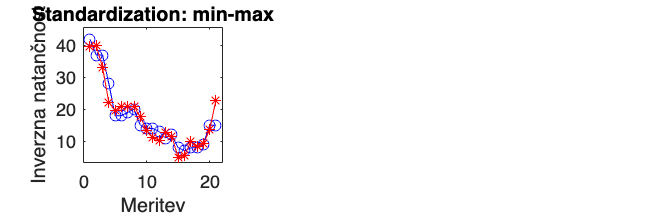


% Adjust figure size to 30x10
set(gcf, 'Position', [100, 100, 3000, 1000]);


% Add common legend below the subplots
%legend('Expected Y (I_{EFF})', 'Calculated Y (I_{EFF_{pred}})', 'Orientation', 'horizontal', 'Position', [0.35, -0.1, 0.3, 0.05]);

%sgtitle('Comparison of Expected and Calculated I_{EFF} for Different Standardizations (PCA)');


## Problem kolinearnosti

% Dodajanje nove meritve x
x_new = 2*T_H2O + 6 + 0.1*randn(size(T_H2O, 1), 1);

% Povezava novih podatkov
X = [A_FLOW T_H2O C_ACID x_new];

% Standardizacija z min-max standardizacijo
min_X = min(X);
max_X = max(X);
X_standardized = (X - min_X) ./ (max_X - min_X);

min_Y = min(I_EFF);
max_Y = max(I_EFF);
Y_standardized = (I_EFF - min_Y) / (max_Y - min_Y);

% PCA
[coeff, score, ~, ~, explained] = pca(X_standardized);

% Izbira glavnih komponent (npr. brez zadnje komponente)
numComponents = size(X_standardized, 2) - 1;
P_reduced = coeff(:, 1:numComponents);


% Projekcija podatkov v novi prostor z zmanjšano dimenzionalnostjo
T_reduced = X_standardized * P_reduced;

% Uporaba LSE v novem prostoru
theta_hat_reduced = (T_reduced' * T_reduced) \ (T_reduced' * Y_standardized);

% Transformacija parametrov nazaj v originalni prostor
theta_hat_PCR = P_reduced * theta_hat_reduced;

% Izračun modela v originalnem prostoru (brez intercepta)
Y_pred_PCR_no_intercept = X_standardized * theta_hat_PCR;

% Izračun intercepta
intercept_PCR = mean(Y_standardized) - mean(Y_pred_PCR_no_intercept);

% Popravek napovedi z dodanim interceptom
Y_pred_PCR = Y_pred_PCR_no_intercept + intercept_PCR;

% Error
error_PCR = Y_standardized - Y_pred_PCR;

% Prikaz rezultatov PCR metode
disp('Model z uporabo PCR metode (min-max standardizacija):');

Model z uporabo PCR metode (min-max standardizacija):


fprintf('Intercept: %.3f\n', intercept_PCR);

Intercept: -0.000


fprintf('I_EFF = %.3f * A_FLOW + %.3f * T_H2O + %.3f * C_ACID + %.3f * x_NEW\n', theta_hat_PCR);

I_EFF = 0.617 * A_FLOW + 0.184 * T_H2O + -0.094 * C_ACID + 0.182 * x_NEW


fprintf('Error variance: %.6f, Error mean: %.6f\n', var(error_PCR), mean(error_PCR));

Error variance: 0.007368, Error mean: -0.000000



% Primerjava z LSE metodo
theta_hat_LSE = (X_standardized' * X_standardized) \ (X_standardized' * Y_standardized);
Y_pred_LSE = X_standardized * theta_hat_LSE;
error_LSE = Y_standardized - Y_pred_LSE;

% Prikaz rezultatov LSE metode
disp('Model z uporabo LSE metode (min-max standardizacija):');

Model z uporabo LSE metode (min-max standardizacija):


fprintf('I_EFF = %.3f * A_FLOW + %.3f * T_H2O + %.3f * C_ACID + %.3f * x_NEW\n', theta_hat_LSE);

I_EFF = 0.589 * A_FLOW + 8.375 * T_H2O + -0.078 * C_ACID + -7.972 * x_NEW


fprintf('Error variance: %.6f, Error mean: %.6f\n', var(error_LSE), mean(error_LSE));

Error variance: 0.005822, Error mean: -0.002517



% Prikaz varianc parametrov izračunanih s poskusi
fprintf('\nEmpirično izračunane variance parametrov (LSE):\n');


Empirično izračunane variance parametrov (LSE):


fprintf('var(theta1) = %.6f; var(theta2) = %.6f; var(theta3) = %.6f; var(theta4) = %.6f;\n', var(theta_hat_LSE));

var(theta1) = 44.613076; var(theta2) = 


fprintf('Empirično izračunane variance parametrov (PCR):\n');

Empirično izračunane variance parametrov (PCR):


fprintf('var(theta1) = %.6f; var(theta2) = %.6f; var(theta3) = %.6f; var(theta4) = %.6f;\n', var(theta_hat_PCR));

var(theta1) = 0.086181; var(theta2) = 

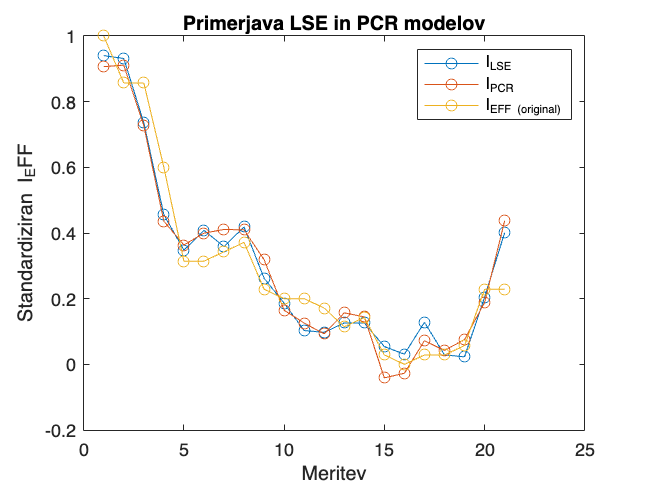


% Prikaz rezultatov na grafu
figure;
plot(Y_pred_LSE, '-o');
hold on;
plot(Y_pred_PCR, '-o');
hold on;
plot(Y_standardized, '-o');
legend({'I_{LSE}', 'I_{PCR}', 'I_{EFF (original)}'});
title('Primerjava LSE in PCR modelov');
xlabel('Meritev');
ylabel('Standardiziran I_EFF');
hold off;

Model using PCR method (min-max standardization):


Intercept: 0.077


I_EFF = -0.280 * A_FLOW + 0.023 * T_H2O + 0.457 * C_ACID


Error variance: 0.109999, Error mean: -0.000000, NRMSE: 1.114


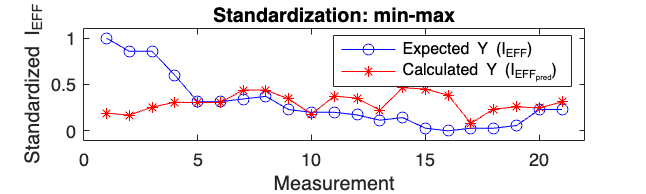

% Funkcija za standardizacijo podatkov
function [X_n, Y_n] = abc(X,Y,n)

    if n == "min-max"
        X_n = (X - min(X)) ./ (max(X) - min(X));
        Y_n = (Y - min(Y)) ./ (max(Y) - min(Y));
    elseif n == "z-score"
        X_n = (X - mean(X)) ./ std(X);
        Y_n = (Y - mean(Y)) ./ std(Y);
    elseif n == "none"
        X_n = X;
        Y_n = Y;
    end
end

% Funkcija za povrnitev standardiziranih podatkov nazaj v originalne vrednosti
function Y_n = abc_rev(Y,n,Y_orig)
    if n == "min-max"
        Y_n = (Y*(max(Y_orig) - min(Y_orig))) + min(Y_orig);
    elseif n == "z-score"
        Y_n = (Y .* std(Y_orig)) + mean(Y_orig);
    end
end

